# Examine Well-Trained OutSeq trials using FISC naive bayesian - Trial Time Alignments

fileDirs = [{'D:\WorkBigDataFiles\PFC\GE11_Session132'},...
    {'D:\WorkBigDataFiles\PFC\GE13_Session083'},...
    {'D:\WorkBigDataFiles\PFC\GE14_Session123'},...
    {'D:\WorkBigDataFiles\PFC\GE17_Session095'},...
    {'D:\WorkBigDataFiles\PFC\GE24_Session096'}];

binSize = 200;
dsRate = 50;

trlWindow = {[-800 2000]};
alignment = {'PokeIn'};
% trlWindow = {[-2000 500]};
% % trlWindow = {[-500 500]};
% alignment = {'PokeOut'};
bayesType = 1; %1 = Poisson: use with raw spike counts; 2 = Bernoulli: use with binarized spike counts; 3 = Gaussian: Use with z-scored spike counts

numChancePerms = 25;

postCLim = [0 0.05];

cMap = load('roma.mat'); % flip
cMap = cMap.(cell2mat(fieldnames(cMap)));
cMap = flipud(cMap);
cMapNanW = cMap;
cMapNanW(1,:) = ones(1,3);

%#ok<*UNRCH>


## Compile Data

tic;
for ani = 1:length(fileDirs)
    %% Create & setup initial object and data variables (if initial file)
    mlb = MLB_SM(fileDirs{ani});
    % Create Analysis Variables
    if ani == 1
        % Behavior Variables
        fiscPokeOutLat = cell(length(fileDirs),1);
        fiscRwdDelivLat = cell(length(fileDirs),1);
        oscPokeOutLat = cell(length(fileDirs),1);
        oscRwdDelivLat = cell(length(fileDirs),1);
        % Posteriors
        realPost_TransMat = cell(mlb.seqLength, mlb.seqLength, length(fileDirs));
        trial_HoldDurs = cell(mlb.seqLength, mlb.seqLength, length(fileDirs));
        chancePost_TransMat = cell(mlb.seqLength, mlb.seqLength, numChancePerms, length(fileDirs));
        realPost_TAO = cell(mlb.seqLength, mlb.seqLength, length(fileDirs));
        chancePost_TAO = cell(mlb.seqLength, mlb.seqLength, numChancePerms, length(fileDirs));
    end
    mlb.binSize = binSize;
    mlb.dsRate = dsRate;
    mlb.windows = trlWindow;
    mlb.alignments = alignment;
    mlb.bayesType = bayesType;

    fiscPokeOutLat{ani} = ([mlb.trialInfo(mlb.fiscTrials(~isnan(mlb.fiscTrials))).PokeOutIndex] - [mlb.trialInfo(mlb.fiscTrials(~isnan(mlb.fiscTrials))).PokeInIndex])'/1000;
    fiscRwdDelivLat{ani} = ([mlb.trialInfo(mlb.fiscTrials(~isnan(mlb.fiscTrials))).RewardIndex] - [mlb.trialInfo(mlb.fiscTrials(~isnan(mlb.fiscTrials))).PokeInIndex])'/1000;
    oscLog = ([mlb.trialInfo.Position] - [mlb.trialInfo.Odor] ~= 0) & [mlb.trialInfo.Performance]==1;
    oscPokeOutLat{ani} = ([mlb.trialInfo(oscLog).PokeOutIndex] - [mlb.trialInfo(oscLog).PokeInIndex])'/1000;
    oscRwdDelivLat{ani} = ([mlb.trialInfo(oscLog).RewardIndex] - [mlb.trialInfo(oscLog).PokeInIndex])'/1000;

    %% Analyze things
    mlb.SetLikes_FISC;
    mlb.Process_Observes;
    trlOdrVect = [mlb.trialInfo(mlb.postTrlIDs).Odor];
    trlPosVect = [mlb.trialInfo(mlb.postTrlIDs).Position];
    trlPerfVect = [mlb.trialInfo(mlb.postTrlIDs).Performance];
    trlHoldDurs = [mlb.trialInfo(mlb.postTrlIDs).PokeDuration];
    tempTmatPosts = cell(mlb.seqLength);
    tempTmatHDs = cell(mlb.seqLength);
    tempTaoPosts = cell(mlb.seqLength);
    for odr = 1:mlb.seqLength
        for pos = 1:mlb.seqLength
            curTrlLog = trlOdrVect==odr & trlPosVect==pos & trlPerfVect==1;
            tempTmatPosts{odr,pos} = mlb.post(:,:,curTrlLog);
            tempTmatHDs{odr,pos} = trlHoldDurs(curTrlLog)';
            if pos~=1 && odr==pos
                for prevOdr = 1:mlb.seqLength
                    if prevOdr~=pos-1 && prevOdr~=pos                                   % This second condition removes skip dupes from the TAO analysis... may be losing significant power?
                        posTAO = find(curTrlLog);
                        prevOdrLog = trlOdrVect(posTAO-1)==prevOdr;
                        tempTaoPosts{prevOdr,pos-1} = mlb.post(:,:,posTAO(prevOdrLog));
                    end
                end
            end
        end
    end
    realPost_TransMat(:,:,ani) = tempTmatPosts;
    trial_HoldDurs(:,:,ani) = tempTmatHDs;
    realPost_TAO(:,:,ani) = tempTaoPosts;
% ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
    % Process Chance
    fprintf('.... processing chance....');
    for perm = 1:numChancePerms 
        mlb.SetLikes_FISC;
        tempRealLikes = mlb.likeTrlSpikes;
        % Permute position ID to disrupt position specific coding
        chancePerm_P = permute(reshape(randperm(numel(mlb.fiscTrials)), size(mlb.fiscTrials)), [1,3,2]);
        tempPosPermLikes = tempRealLikes(chancePerm_P);
        % Permute temporal organization to disrupt temporal coding 
        tempFullPermLikes = tempPosPermLikes;   % Use the position permuted data for the full permutation
        for t = 1:numel(tempRealLikes)
            chancePerm_T = randperm(size(mlb.likeTrlSpikes{t},1));
            tempFullPermLikes{t} = tempFullPermLikes{t}(chancePerm_T,:);
        end
        mlb.likeTrlSpikes = tempFullPermLikes;
        mlb.Process_Observes;
        for odr = 1:mlb.seqLength
            for pos = 1:mlb.seqLength
                curTrlLog = trlOdrVect==odr & trlPosVect==pos & trlPerfVect==1;
                chancePost_TransMat{odr,pos,perm,ani} = mlb.post(:,:,curTrlLog);
                if pos~=1 && odr==pos
                    for prevOdr = 1:mlb.seqLength
                        if prevOdr~=pos-1 && prevOdr~=pos                                   % This second condition removes skip dupes from the TAO analysis... may be losing significant power?
                            posTAO = find(curTrlLog);
                            prevOdrLog = trlOdrVect(posTAO-1)==prevOdr;
                            chancePost_TAO{prevOdr,pos-1,perm,ani} = mlb.post(:,:,posTAO(prevOdrLog));
                        end
                    end
                end
            end
        end
    end
    fprintf('Complete\n');
end

Compiling StatMatrix Data....Completed


.... processing chance....

Complete


Compiling StatMatrix Data....Completed


.... processing chance....

Complete


Compiling StatMatrix Data....Completed


.... processing chance....

Complete


Compiling StatMatrix Data....Completed


.... processing chance....

Complete


Compiling StatMatrix Data....Completed


.... processing chance....

Complete


pokeOutLats = cell2mat(fiscPokeOutLat(:));
oscPOlats = cell2mat(oscPokeOutLat(:));
rwdDelivLat = cell2mat(fiscRwdDelivLat(:));
oscRWDlats = cell2mat(oscRwdDelivLat(:));
if strcmp(alignment{1}, 'PokeIn')
    nearestPOtime = mlb.obsvTimeVect(find(mlb.obsvTimeVect<median(pokeOutLats),1,'last'));
    nearestPOtimeOSC = mlb.obsvTimeVect(find(mlb.obsvTimeVect<median(oscPOlats),1,'last'));
    nearestRWDtime = mlb.obsvTimeVect(find(mlb.obsvTimeVect<median(rwdDelivLat),1,'last'));
    nearestRWDtimeOSC = mlb.obsvTimeVect(find(mlb.obsvTimeVect<median(oscRWDlats),1,'last'));
elseif strcmp(alignment{1}, 'PokeOut')
    nearestPOtime = mlb.obsvTimeVect(find(mlb.obsvTimeVect>median(pokeOutLats*-1),1,'first'));
    nearestPOtimeOSC = mlb.obsvTimeVect(find(mlb.obsvTimeVect>median(oscPOlats*-1),1,'first'));
    nearestRWDtime = mlb.obsvTimeVect(find(mlb.obsvTimeVect>median(rwdDelivLat-pokeOutLats),1,'first'));
    nearestRWDtimeOSC = mlb.obsvTimeVect(find(mlb.obsvTimeVect>median(oscRWDlats-oscPOlats),1,'first'));
end

piNdx = find(mlb.likeTimeVect==0)+0.5;
poNdx = find(mlb.likeTimeVect==nearestPOtime)+0.5;
rwdNdx = find(mlb.likeTimeVect==nearestRWDtime)+0.5;
posNdx = find(diff(mlb.likeTimeVect)<0)+0.5;
toc

Elapsed time is 590.269177 seconds.


## Combine trials across animals & compute trial marginals

tic;
groupTransMat_Real = cell(mlb.seqLength);
groupTrial_HoldDurs = cell(mlb.seqLength);
groupTransMat_RealPos = cell(mlb.seqLength);
groupTransMat_RealERR = cell(mlb.seqLength);
groupTransMat_RealPosERR = cell(mlb.seqLength);
groupTransMat_Chance = cell(mlb.seqLength);
groupTransMat_ChancePos = cell(mlb.seqLength);
groupTAO_Real = cell(mlb.seqLength);
groupTAO_RealPos = cell(mlb.seqLength);
groupTAO_Chance = cell(mlb.seqLength);
groupTAO_ChancePos = cell(mlb.seqLength);
for odr = 1:mlb.seqLength
    for pos = 1:mlb.seqLength
        groupTransMat_Real{odr,pos} = cell2mat(realPost_TransMat(odr,pos,:));
        groupTrial_HoldDurs{odr,pos} = cell2mat(squeeze(trial_HoldDurs(odr,pos,:)));
        groupTransMat_RealPos{odr,pos} = mlb.TabulateBayesPost(groupTransMat_Real{odr,pos}, mlb.decodeIDvects(:,3));
        groupTAO_Real{odr,pos} = cell2mat(realPost_TAO(odr,pos,:));
        groupTAO_Real{odr,pos} = mlb.TabulateBayesPost(groupTAO_Real{odr,pos}, mlb.decodeIDvects(:,3));

        groupTransMat_Chance{odr,pos} = mean(cell2mat(reshape(squeeze(chancePost_TransMat(odr,pos,:,:)), [1,1,numel(chancePost_TransMat(odr,pos,:,:))])),3,'omitnan');
        groupTransMat_ChancePos{odr,pos} = mean(mlb.TabulateBayesPost(cell2mat(reshape(squeeze(chancePost_TransMat(odr,pos,:,:)), [1,1,numel(chancePost_TransMat(odr,pos,:,:))])), mlb.decodeIDvects(:,3)),3,'omitnan');
        groupTAO_Chance{odr,pos} = mean(cell2mat(reshape(squeeze(chancePost_TAO(odr,pos,:,:)), [1,1,numel(chancePost_TAO(odr,pos,:,:))])),3,'omitnan');
        groupTAO_ChancePos{odr,pos} = mean(mlb.TabulateBayesPost(cell2mat(reshape(squeeze(chancePost_TAO(odr,pos,:,:)), [1,1,numel(chancePost_TAO(odr,pos,:,:))])), mlb.decodeIDvects(:,3)),3,'omitnan');
    end
end
toc

Elapsed time is 11.373909 seconds.


## Plot Temporal PDF

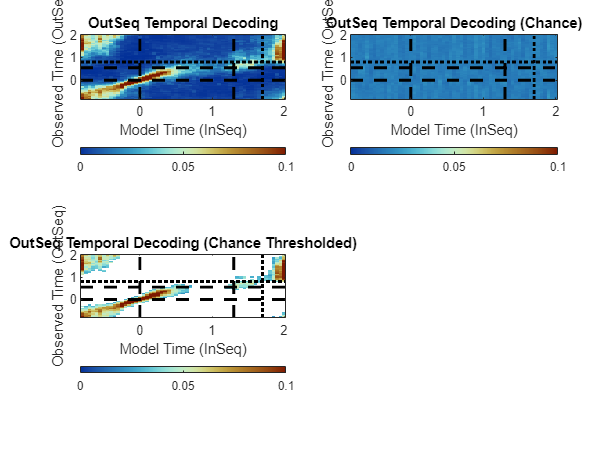

sps = nan(2);
figure;
outSeq_PDF = cell2mat(reshape(groupTransMat_Real(~eye(mlb.seqLength)), [1,1,numel(groupTransMat_Real(~eye(mlb.seqLength)))]));
tempTimeDecode = mlb.TabulateBayesPost(outSeq_PDF, mlb.decodeIDvects(:,1));
tempObsvProbs = mean(tempTimeDecode,3);
sps(1) = subplot(2,2,1);
imagesc(mlb.obsvTimeVect,mlb.obsvTimeVect, tempObsvProbs, postCLim*2);
hold on;
set(gca, 'ydir', 'normal');
colormap(sps(1), cMap);
title('OutSeq Temporal Decoding');
hold on;
plot(zeros(1,2), get(gca, 'ylim'), '--k', 'linewidth', 2);
plot(repmat(nearestPOtime, [1,2]), get(gca, 'ylim'), '--k', 'linewidth', 2);
plot(repmat(nearestRWDtime, [1,2]), get(gca, 'ylim'), ':k', 'linewidth', 2);
plot(get(gca, 'xlim'), zeros(1,2), '--k', 'linewidth', 2);
plot(get(gca, 'xlim'), repmat(nearestPOtimeOSC, [1,2]), '--k', 'linewidth', 2);
plot(get(gca, 'xlim'), repmat(nearestRWDtimeOSC, [1,2]), ':k', 'linewidth', 2);
xlabel('Model Time (InSeq)');
ylabel('Observed Time (OutSeq)');
colorbar(gca, 'location', 'southoutside');

outSeqChance_PDF = cell2mat(reshape(groupTransMat_Chance(~eye(mlb.seqLength)), [1,1,numel(groupTransMat_Chance(~eye(mlb.seqLength)))]));
tempTimeDecodeChance = mean(mlb.TabulateBayesPost(outSeqChance_PDF, mlb.decodeIDvects(:,1)),3, 'omitnan');
sps(2) = subplot(2,2,2);
imagesc(mlb.obsvTimeVect,mlb.obsvTimeVect, tempTimeDecodeChance, postCLim*2);
hold on;
set(gca, 'ydir', 'normal');
colormap(sps(2),cMap);
title('OutSeq Temporal Decoding (Chance)');
hold on;
plot(zeros(1,2), get(gca, 'ylim'), '--k', 'linewidth', 2);
plot(repmat(nearestPOtime, [1,2]), get(gca, 'ylim'), '--k', 'linewidth', 2);
plot(repmat(nearestRWDtime, [1,2]), get(gca, 'ylim'), ':k', 'linewidth', 2);
plot(get(gca, 'xlim'), zeros(1,2), '--k', 'linewidth', 2);
plot(get(gca, 'xlim'), repmat(nearestPOtimeOSC, [1,2]), '--k', 'linewidth', 2);
plot(get(gca, 'xlim'), repmat(nearestRWDtimeOSC, [1,2]), ':k', 'linewidth', 2);
xlabel('Model Time (InSeq)');
ylabel('Observed Time (OutSeq)');
colorbar(gca, 'location', 'southoutside');

sigVal = nan(size(tempObsvProbs));
for t1 = 1:length(mlb.obsvTimeVect)
    for t2 = 1:length(mlb.obsvTimeVect)
        [~,sigVal(t1,t2)] = ttest(tempTimeDecode(t1,t2,:), tempTimeDecodeChance(t1,t2), 'Tail', 'Right');
    end
end
% sigLog = sigVal<0.05;
[~,q] = mafdr(sigVal(:));
sigLog = reshape(q,size(sigVal))<0.05;
tempObsvProbs(~sigLog) = nan;
tempObsvProbs(tempObsvProbs==0) = 1e-100;
sps(3) = subplot(2,2,3);
imagesc(mlb.obsvTimeVect, mlb.obsvTimeVect, tempObsvProbs, postCLim*2);
hold on;
set(gca, 'ydir', 'normal');
colormap(sps(3), cMapNanW);
title('OutSeq Temporal Decoding (Chance Thresholded)');
hold on;
plot(zeros(1,2), get(gca, 'ylim'), '--k', 'linewidth', 2);
plot(repmat(nearestPOtime, [1,2]), get(gca, 'ylim'), '--k', 'linewidth', 2);
plot(repmat(nearestRWDtime, [1,2]), get(gca, 'ylim'), ':k', 'linewidth', 2);
plot(get(gca, 'xlim'), zeros(1,2), '--k', 'linewidth', 2);
plot(get(gca, 'xlim'), repmat(nearestPOtimeOSC, [1,2]), '--k', 'linewidth', 2);
plot(get(gca, 'xlim'), repmat(nearestRWDtimeOSC, [1,2]), ':k', 'linewidth', 2);
xlabel('Model Time (InSeq)');
ylabel('Observed Time (OutSeq)');
colorbar(gca, 'location', 'southoutside');

## Compare Temporal Decoding with Hold Durations

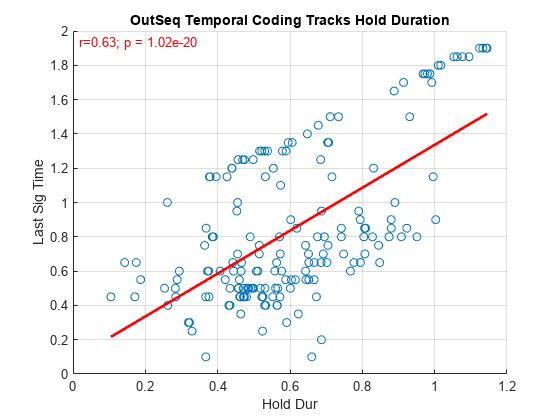


outSeq_HDs = cell2mat(groupTrial_HoldDurs(~eye(mlb.seqLength)));

realTimeDiags = nan(length(mlb.obsvTimeVect), size(tempTimeDecode,3));
timeDiagMeasure = nan(size(tempTimeDecode,3),1);
chanceTimeDiag = tempTimeDecodeChance(logical(eye(length(mlb.obsvTimeVect))));
% chanceTimeDiag = ones(size(chanceTimeDiag))*mean(chanceTimeDiag);
netSize = 1;
for trl = 1:size(tempTimeDecode,3)
    tempTimeMtx = tempTimeDecode(:,:,trl);
    for t = 1:length(mlb.obsvTimeVect)
        if t == 1
            tempVals = tempTimeMtx(t:t+netSize,t:t+netSize);
        elseif t-netSize<1
            tempVals = tempTimeMtx(1:t+netSize, 1:t+netSize);
        elseif t == length(mlb.obsvTimeVect)
            tempVals = tempTimeMtx(t-netSize:t,t-netSize:t);
        elseif t+netSize>length(mlb.obsvTimeVect)
            tempVals = tempTimeMtx(t-netSize:end,t-netSize:end);
        else
            tempVals = tempTimeMtx(t-netSize:t+netSize,t-netSize:t+netSize);
        end
        realTimeDiags(t,trl) = mean(tempVals(:));
    end
    realTimeDiags(:,trl) = smooth(realTimeDiags(:,trl));
%     timeDiagMeasure(trl) = sum(realTimeDiags(:,trl)>chanceTimeDiag); yLbl = '% Time Significant';
    realTimeDiags(mlb.obsvTimeVect<0,trl) = 0.1;  % Effectively remove timepoints prior to port entry
    realTimeDiags(mlb.obsvTimeVect>outSeq_HDs(trl)+0.8,trl) = 0; % Effectively remove timepoints well into the ITI period
%     timeDiagMeasure(trl) = mlb.obsvTimeVect(find(realTimeDiags(:,trl)<chanceTimeDiag,1,'first')); yLbl = 'First Chance Time';
    timeDiagMeasure(trl) = mlb.obsvTimeVect(find(realTimeDiags(:,trl)>chanceTimeDiag,1,'last')); yLbl = 'Last Sig Time';
end
figure; 
mlb.CorrScatPlot(outSeq_HDs, timeDiagMeasure, 'Hold Dur', yLbl, 'gridOn');
% set(gca, 'xlim', cell2mat(trlWindow)/1000, 'ylim', cell2mat(trlWindow)/1000);
title('OutSeq Temporal Coding Tracks Hold Duration');

## Compile OutSeq Odor & Position Probabilities

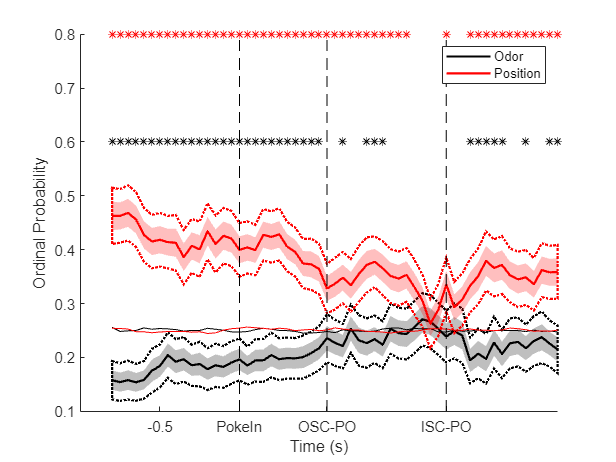

outSeq_OdrProb = cell(mlb.seqLength);
outSeq_PosProb = cell(mlb.seqLength);
outSeq_OdrProbChance = cell(mlb.seqLength);
outSeq_PosProbChance = cell(mlb.seqLength);
for odr = 1:mlb.seqLength
    for pos = 1:mlb.seqLength
        if odr~=pos
            outSeq_OdrProb{odr,pos} = groupTransMat_RealPos{odr,pos}(:,odr,:);
            outSeq_PosProb{odr,pos} = groupTransMat_RealPos{odr,pos}(:,pos,:);
            
            outSeq_OdrProbChance{odr,pos} = groupTransMat_ChancePos{odr,pos}(:,odr,:);
            outSeq_PosProbChance{odr,pos} = groupTransMat_ChancePos{odr,pos}(:,pos,:);
        end
    end
end
outSeq_OdrProb = squeeze(cell2mat(reshape(outSeq_OdrProb, [1,1,numel(outSeq_OdrProb)])));
outSeq_PosProb = squeeze(cell2mat(reshape(outSeq_PosProb, [1,1,numel(outSeq_PosProb)])));
outSeq_OdrProbChance = mean(cell2mat(reshape(outSeq_OdrProbChance, [1,1,numel(outSeq_OdrProbChance)])),3,'omitnan');
outSeq_PosProbChance = mean(cell2mat(reshape(outSeq_PosProbChance, [1,1,numel(outSeq_PosProbChance)])),3,'omitnan');
plts = nan(1,2);
figure; 
plts(1) = mlb.PlotMeanVarLine(mlb.obsvTimeVect, outSeq_OdrProb,2,0.05,'k');
plts(2) = mlb.PlotMeanVarLine(mlb.obsvTimeVect, outSeq_PosProb,2,0.05,'r');
plot(mlb.obsvTimeVect, outSeq_OdrProbChance, 'k');
plot(mlb.obsvTimeVect, outSeq_PosProbChance, 'r');

posSigLog = false(1,length(mlb.obsvTimeVect));
odrSigLog = false(1,length(mlb.obsvTimeVect));
opDiffSigLog = false(1,length(mlb.obsvTimeVect));
for t = 1:length(mlb.obsvTimeVect)
    posSigLog(t) = ttest(outSeq_PosProb(t,:), outSeq_OdrProbChance(t), 'Alpha', 0.05/length(mlb.obsvTimeVect), 'Tail', 'Right');
    odrSigLog(t) = ttest(outSeq_OdrProb(t,:), outSeq_PosProbChance(t), 'Alpha', 0.05/length(mlb.obsvTimeVect), 'Tail', 'Right');
    opDiffSigLog(t) = ttest(outSeq_PosProb(t,:), outSeq_OdrProb(t,:), 'Alpha', 0.05/length(mlb.obsvTimeVect), 'Tail', 'Right');
end
posSigLog = posSigLog*.8;
posSigLog(posSigLog==0) = nan;
scatter(mlb.obsvTimeVect, posSigLog, '*r');

odrSigLog = odrSigLog*.7;
odrSigLog(odrSigLog==0) = nan;
scatter(mlb.obsvTimeVect, odrSigLog, '*k');

opDiffSigLog = opDiffSigLog*.6;
opDiffSigLog(opDiffSigLog==0) = nan;
scatter(mlb.obsvTimeVect, opDiffSigLog, '*k');

plot(zeros(1,2), get(gca,'ylim'), '--k');
plot(repmat(nearestPOtimeOSC, [1,2]), get(gca, 'ylim'), '--k');
plot(repmat(nearestPOtime, [1,2]), get(gca, 'ylim'), '--k');

if strcmp(alignment{1}, 'PokeIn')
    set(gca, 'xtick', [-0.5 0 nearestPOtimeOSC, nearestPOtime], 'xticklabels', [{'-0.5'}, alignment{1}, {'OSC-PO'}, {'ISC-PO'}]);
elseif strcmp(alignment{1}, 'PokeOut')
    set(gca, 'xtick', [nearestPOtime, nearestPOtimeOSC, 0, 0.5], 'xticklabels', [{'ISC-PI'}, {'OSC-PI'}, alignment{1}, {'0.5'}]);
end
ylabel('Ordinal Probability');
xlabel('Time (s)');
legend(plts, [{'Odor'}, {'Position'}]);